**Testul 7**

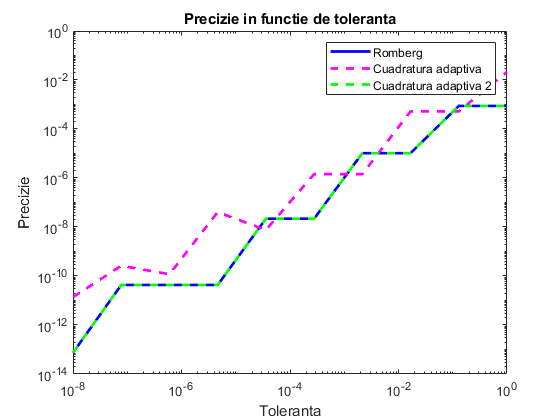

f = @(x) 2./(1+x.^2);
a = -1;
b = 1;

% Voi testa cu valorile tolerantei intre 1e-8 si 1e0, pentru 10 puncte
tolerances = logspace(-8, 0, 10); 

Romberg_results = zeros(length(tolerances), 2);
Adquad_results = zeros(length(tolerances), 2);
Adquad_results2 = zeros(length(tolerances), 2);

% Pentru fiecare toleranta calculez aproximarea cu metoda lui Romberg si cu
% cudratura adaptiva
for i = 1:length(tolerances)
    [Romberg_results(i,1), Romberg_results(i,2)] = Romberg(f, a, b, tolerances(i));
    [Adquad_results(i,1), Adquad_results(i,2)] = adquad(f, a, b, tolerances(i));
    [Adquad_results2(i,1), Adquad_results2(i,2)] = adquad2(f, a, b, tolerances(i), @Romberg);
end

% Calcul erori
Romberg_error = abs(Romberg_results(:,1) - pi);
Adquad_error = abs(Adquad_results(:,1) - pi);
Adquad_error2 = abs(Adquad_results2(:,1) - pi);

figure;
loglog(tolerances, Romberg_error, 'b-', 'LineWidth', 2);
hold on;
loglog(tolerances, Adquad_error, 'm--', 'LineWidth', 2);
loglog(tolerances, Adquad_error2, 'g--', 'LineWidth', 2);
xlabel('Toleranta');
ylabel('Precizie');
legend('Romberg', 'Cuadratura adaptiva', 'Cuadratura adaptiva 2');
title('Precizie in functie de toleranta');

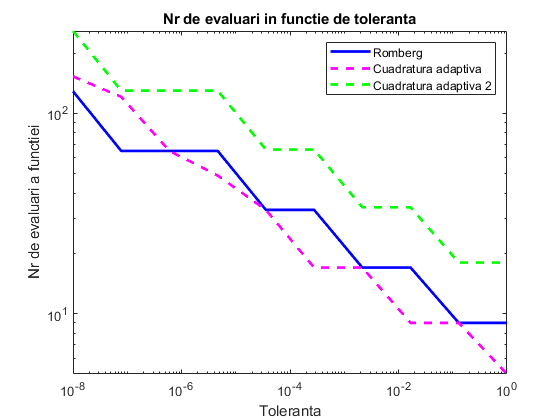


figure;
loglog(tolerances, Romberg_results(:,2), 'b-', 'LineWidth', 2);
hold on;
loglog(tolerances, Adquad_results(:,2), 'm--', 'LineWidth', 2);
loglog(tolerances, Adquad_results2(:,2), 'g--', 'LineWidth', 2);
xlabel('Toleranta');
ylabel('Nr de evaluari a functiei');
legend('Romberg', 'Cuadratura adaptiva', 'Cuadratura adaptiva 2');
title('Nr de evaluari in functie de toleranta');

Observatii:

Din primul grafic observam ca toleranta descreste odata cu precizia, deci cu cat toleranta devine mai mica, cu atat aproximarea integralei se imbunatateste pentru ambele metode.

Din al doilea grafic observam ca numarul de evaluari al functieie creste in timp ce toleranta descreste, deci o toleranta mai stricta implica un numar mai mare de evaluari a functiei in cazul ambelor metode.